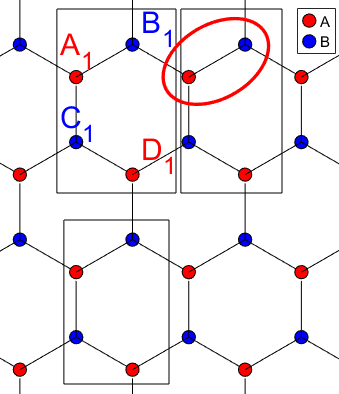

红圈部分为unit cell 内部hopping为$t_{1\;}$ 胞间跃迁为$t_2$

N_row = 1;
N_col = 3;


epsilon_A = 0;
epsilon_B = 0;
t_1 = 1;
t_2 = 2;

H_00 = [epsilon_A, t_1, t_2, 0;
        t_1, epsilon_B, 0, 0;
        t_2, 0, epsilon_B, t_1;
        0, 0, t_1, epsilon_A];
H_0x = [0, 0, 0, 0;
        0, t_2, 0, 0;
        0, 0, 0, 0;
        0, 0, t_1, 0];

% 构造横向跃迁元

temp = full(get_Nearest_Square_Hopping_Sparse(N_col, N_row, 1, 0));
temp = triu(kron(full(temp), H_0x));
H_inter_x = temp + temp';

% 构造纵向跃迁元 Transition between row
% temp = get_Nearest_Square_Hopping_Sparse(N_col, N_row, 0, 1);
% temp_vect = [0,0,0,0;0,0,0,0;1,0,0,0;0,1,0,0];
% temp = tril(kron(full(temp),temp_vect'));
% H_inter_y = temp + temp';

H = kron(eye(N_row*N_col), H_00) + H_inter_x;




